# ** Explore the Algorithms**

## **This experiment is for going through the whole procedures according to the doctoral disseration.**

**Generate the pattern.**

[pattern, patternPath] = generatePattern(2048, 1536, 50, 200, 6, 0, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p0.00_B.bmp is already generated!


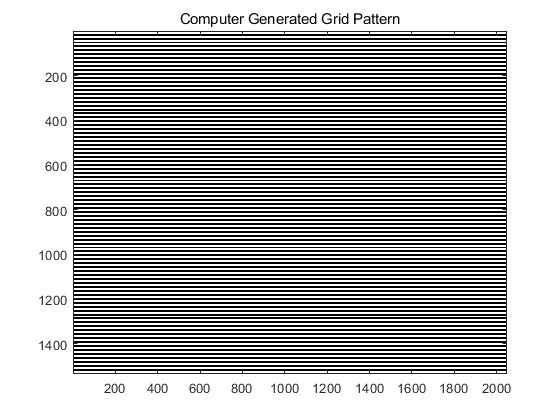

displayFig(pattern, 'Computer Generated Grid Pattern');

Display the captured image, which is acquired by projecting the grid on the curve surface object.

figCapturedPath = char("..\Experiments\Ex 3D reconstruction\pic1\px.bmp")

figCapturedPath = '..\Experiments\Ex 3D reconstruction\pic1\px.bmp'

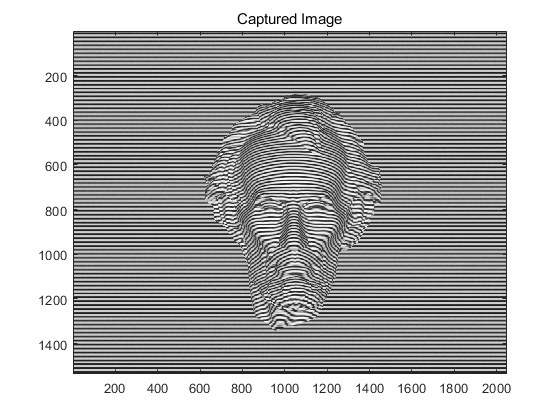

figCaptured = imread(figCapturedPath);
figCaptured = rgb2gray(figCaptured);
figCaptured = mat2gray(figCaptured, [0, 255]);
displayFig(figCaptured, 'Captured Image');

    Then, we have four more phase shifted image to digitally generate.

- The zero phase shift: we just impose computer generated grid on the captured image.

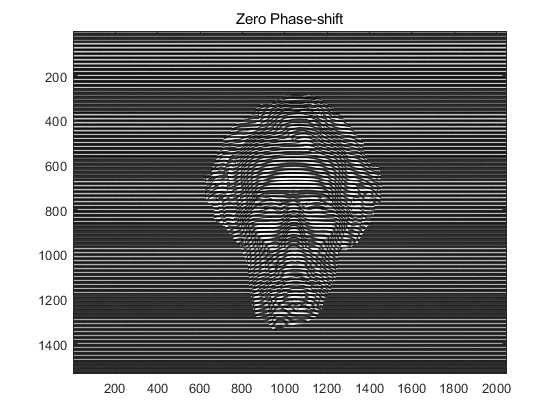

figZeroPS = figCaptured .* pattern;
displayFig(figZeroPS, "Zero Phase-shift");

-  Shift the computer generated grid with the phase pi  and superimpose on the captured frame.

patternPiPS = generatePattern(2048, 1536, 50, 200, 6, 3, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p3.00_B.bmp is already generated!


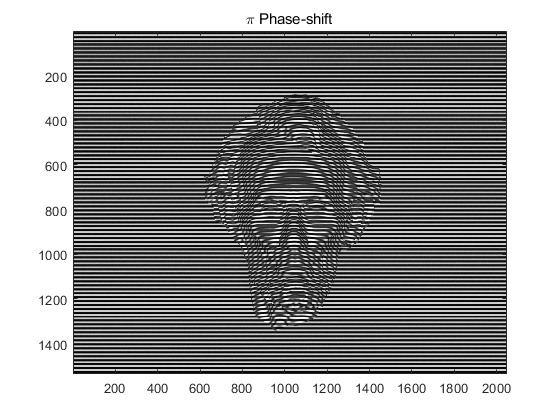

figPiPS = patternPiPS .* figCaptured;
displayFig(figPiPS, '\pi Phase-shift')

- Shift and impose the grid by the smallest phase \delta of a pixel. in our case, \delta = 2\pi / 6;                                                                                                                                                                                                                                                                                                                                 

patternDeltaPS = generatePattern(2048, 1536, 50, 200, 6, 1, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p1.00_B.bmp is already generated!


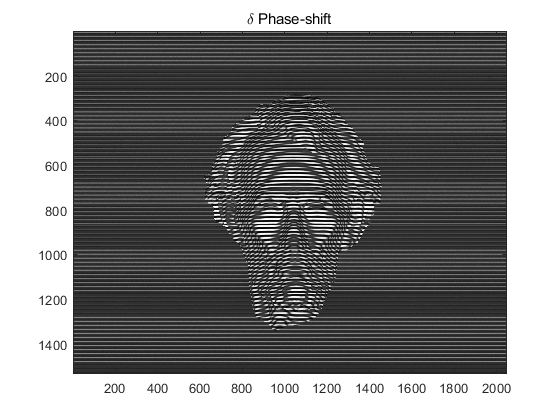

figDeltaPS = patternDeltaPS .* figCaptured;
displayFig(figDeltaPS, '\delta Phase-shift')

- Shift the gird with phase of \delta + \pi and superimpose. 

patternDeltaPiPS = generatePattern(2048, 1536, 50, 200, 6, 4, 1);

Pattern ---- w2048_h1536_g50_200_wl6_p4.00_B.bmp is already generated!


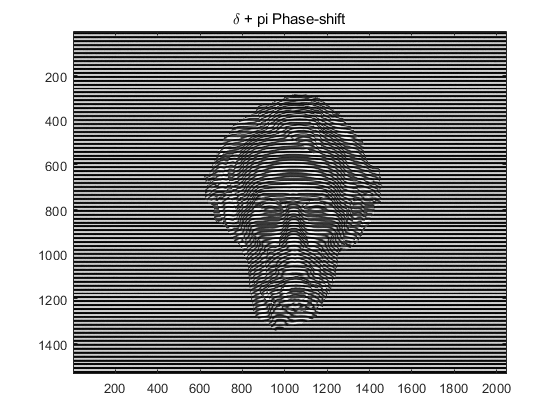

figDeltaPiPS = patternDeltaPiPS .* figCaptured;
displayFig(figDeltaPiPS, '\delta + pi Phase-shift');

Above are the four frames we generated to produce a great phase map. Then we can remove the grid in each frame to generate the phase maps.

We can also use digitalMorieSuperImpose function to generate the four figures at once.

Pattern ---- w2048_h1536_g50_200_wl6_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p3.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p1.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p4.00_B.bmp is already generated!
Figure on ..\Experiments\Ex 3D reconstruction\pic1\p0.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic1\p3.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic1\p1.bmp is generated.
Figure on ..\Experiments\Ex 3D reconstruction\pic1\p4.bmp is generated.


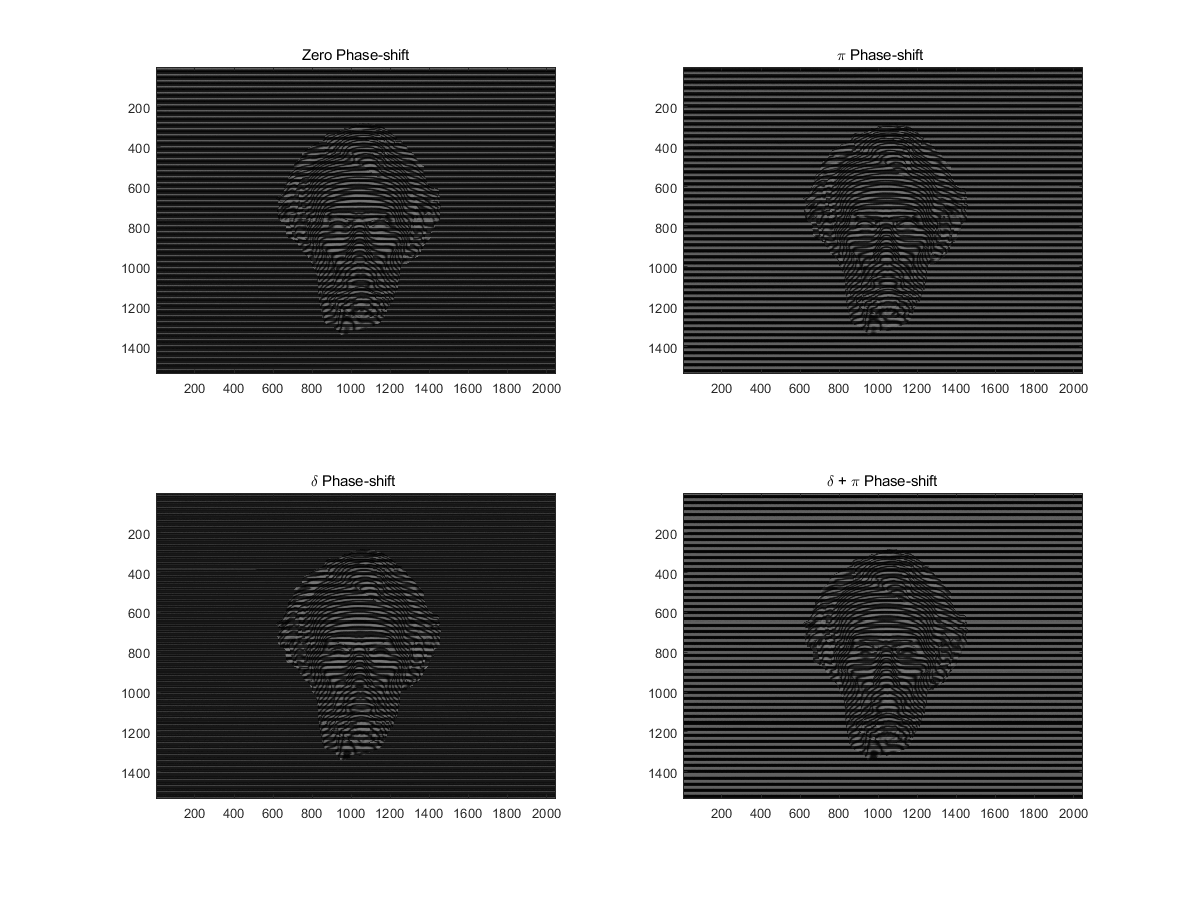

[fig0, fig1, fig2, fig3] = digitalMorieSuperimpose(figCapturedPath, patternPath, 1, true);

However, I will stick to the previous "figZeroPS" naming strategy. Then we can extract the morie patterns.Frist we will look at the last frame, the frame with \delta  + \pi phase shift. Our goal is to find best hyperparameters for optimizing the FFT-SWT grid removal method.

**Grid Removal**

sanity-check the SWTFFT algorithm. 

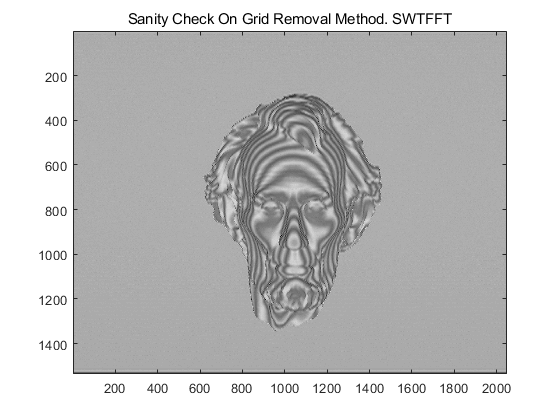

figFiltered = SWTFFT(figDeltaPiPS,3, 'db5', 20);
displayFig(figFiltered, 'Sanity Check On Grid Removal Method. SWTFFT');

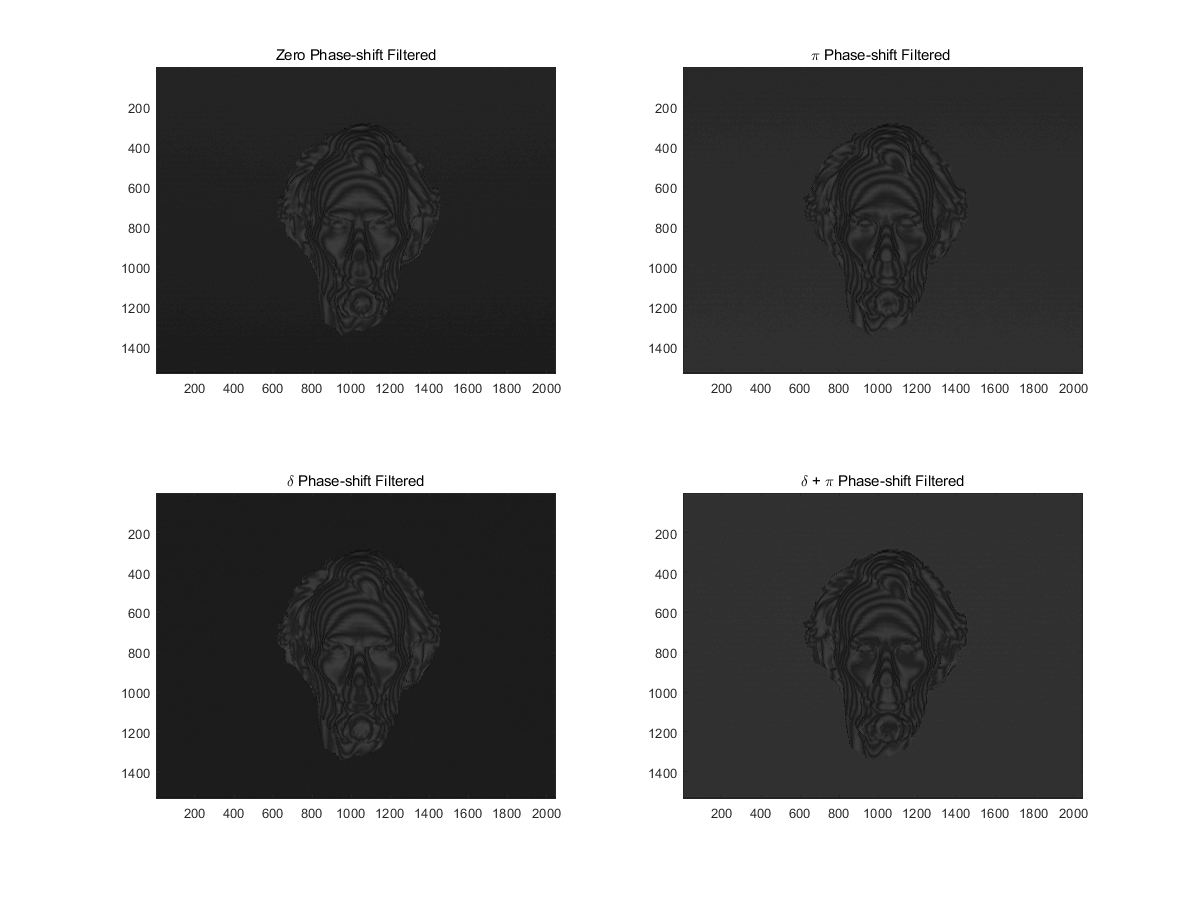

[figZeroPSFiltered, figPiPSFiltered, figDeltaPSFiltered, figDeltaPiPSFiltered] = removeGridSWTFFT(figZeroPS, figPiPS, figDeltaPS, figDeltaPiPS, 3, 'db5', 20, true);

Then, we can check our method for extracting wrapped phase

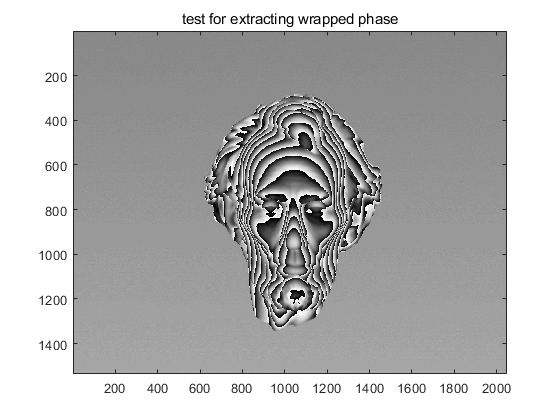

wrappedPhase = extractWrappedPhaseSWTFFT(figZeroPSFiltered, figPiPSFiltered, figDeltaPSFiltered, figDeltaPiPSFiltered, pi / 3, true);

Compared to our earlier, deformed image, we can easily  seen the grids has been diminished.

Now, we need to optimized aournd decNum = 3, wName = "db5" and sigma = 20. since they have already a good job.

First, vary decomposation and keep other parameters constant.

## Unwrapping

Then we can unwrap the phase we get.

I  choose to use the three-wavelength phase-unwrapping method.

lambda1 = 6;
lambda2 = 10;
lambda3 = 12;
wrappedPhase1 = getSingleUnwrappedPhase(lambda1);

Pattern ---- w2048_h1536_g50_200_wl6_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p3.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p1.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl6_p4.00_B.bmp is already generated!
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic1\p0.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic1\p3.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic1\p1.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic1\p4.bmp is generated.


wrappedPhase2 = getSingleUnwrappedPhase(lambda2);

Pattern ---- w2048_h1536_g50_200_wl10_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl10_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl10_p5.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl10_p1.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl10_p6.00_B.bmp is already generated!
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic2\p0.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic2\p5.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic2\p1.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic2\p6.bmp is generated.


wrappedPhase3 = getSingleUnwrappedPhase(lambda3);

Pattern ---- w2048_h1536_g50_200_wl12_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl12_p0.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl12_p6.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl12_p1.00_B.bmp is already generated!
Pattern ---- w2048_h1536_g50_200_wl12_p7.00_B.bmp is already generated!
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic3\p0.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic3\p6.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic3\p1.bmp is generated.
Figure on H:\张凡的本科论文\Experiments\Ex 3D reconstruction\pic3\p7.bmp is generated.


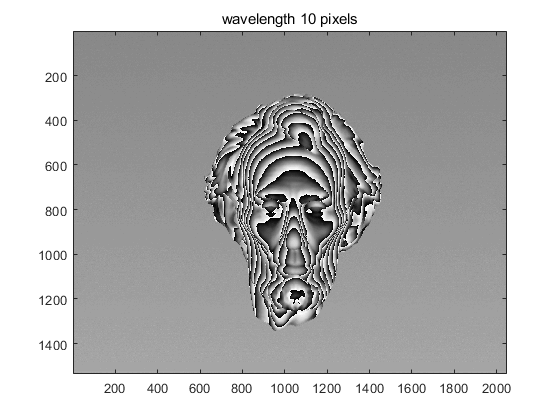

displayFig(wrappedPhase1, "wavelength 6 pixels");

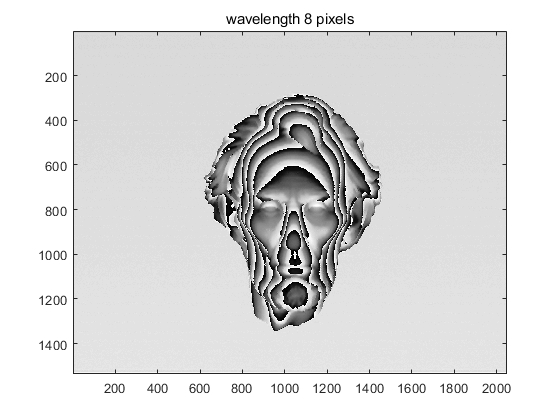

displayFig(wrappedPhase2, "wavelength 10 pixels");

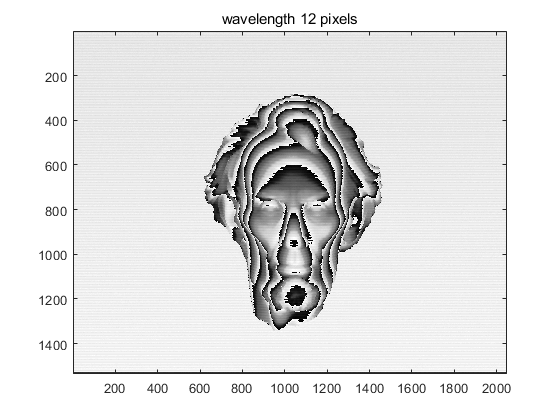

displayFig(wrappedPhase3, "wavelength 12 pixels"); 

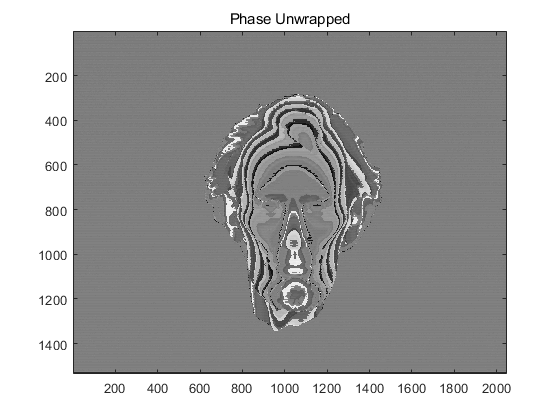

unwrappedPhase = unwrapPhase3(wrappedPhase1, wrappedPhase2, wrappedPhase3, lambda1, lambda2, lambda3);
displayFig(unwrappedPhase, "Phase Unwrapped");